clear
% Sistema QAM
n=1000;
R=50; % bps
T=1/R;
Upf=10;
Ts=T/Upf;
t=0:Ts:(n*T)

t =          0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580    0.0600    0.0620    0.0640    0.0660    0.0680    0.0700    0.0720    0.0740    0.0760    0.0780    0.0800    0.0820    0.0840    0.0860    0.0880    0.0900    0.0920    0.0940    0.0960    0.0980


fs=1/Ts;

% Constelacion

M=4;
A=2;
valores=-(sqrt(M)-1):2:(sqrt(M)-1);
[Re, Im] =meshgrid(valores, valores);
constell=A*(Re+1i*Im);
constell=reshape(constell,1,numel(constell))

constell =   -2.0000 - 2.0000i  -2.0000 + 2.0000i   2.0000 - 2.0000i   2.0000 + 2.0000i


constell'

ans =   -2.0000 + 2.0000i
  -2.0000 - 2.0000i
   2.0000 + 2.0000i
   2.0000 - 2.0000i


% Generacion de simbolos

s=datasample(constell,n)

s =    2.0000 - 2.0000i   2.0000 + 2.0000i   2.0000 + 2.0000i   2.0000 - 2.0000i  -2.0000 + 2.0000i   2.0000 + 2.0000i  -2.0000 - 2.0000i   2.0000 + 2.0000i   2.0000 + 2.0000i  -2.0000 - 2.0000i  -2.0000 - 2.0000i   2.0000 + 2.0000i  -2.0000 + 2.0000i  -2.0000 - 2.0000i  -2.0000 + 2.0000i   2.0000 + 2.0000i  -2.0000 + 2.0000i   2.0000 - 2.0000i   2.0000 - 2.0000i   2.0000 + 2.0000i   2.0000 - 2.0000i   2.0000 - 2.0000i   2.0000 + 2.0000i   2.0000 - 2.0000i   2.0000 + 2.0000i   2.0000 + 2.0000i  -2.0000 + 2.0000i   2.0000 - 2.0000i  -2.0000 - 2.0000i  -2.0000 - 2.0000i   2.0000 + 2.0000i  -2.0000 - 2.0000i  -2.0000 - 2.0000i  -2.0000 - 2.0000i   2.0000 - 2.0000i   2.0000 - 2.0000i  -2.0000 + 2.0000i   2.0000 + 2.0000i  -2.0000 + 2.0000i  -2.0000 + 2.0000i  -2.0000 + 2.0000i  -2.0000 + 2.0000i  -2.0000 - 2.0000i   2.0000 + 2.0000i   2.0000 + 2.0000i  -2.0000 - 2.0000i  -2.0000 + 2.0000i  -2.0000 - 2.0000i   2.0000 + 2.0000i  -2.0000 + 2.0000i


% s=[zeros(1,n/2) 1 zeros(1,(n/2)-1)]
% s=ones(1,n)

sk=[0 upsample(s,(Upf))]

sk =    0.0000 + 0.0000i   2.0000 - 2.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   2.0000 + 2.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   2.0000 + 2.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   2.0000 - 2.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -2.0000 + 2.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i


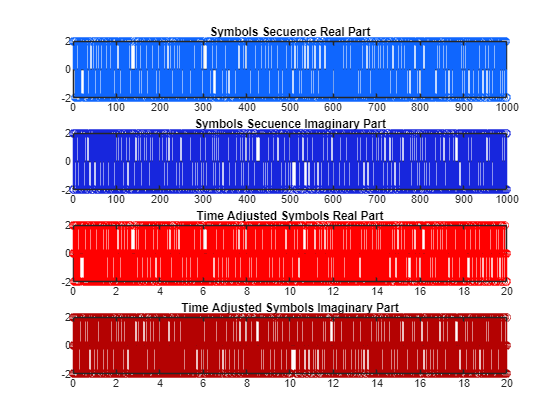


figure
subplot(411),stem(real(s),'Color','#0f66fe'),grid
title('Symbols Secuence Real Part')
subplot(412),stem(imag(s),'Color','#1726dd'),grid
title('Symbols Secuence Imaginary Part')
subplot(413),stem(t,real(sk),'r'),grid
title('Time Adjusted Symbols Real Part')
subplot(414),stem(t,imag(sk),'Color','#b40202'),grid
title('Time Adjusted Symbols Imaginary Part')
xlim([0 t(length(t))])

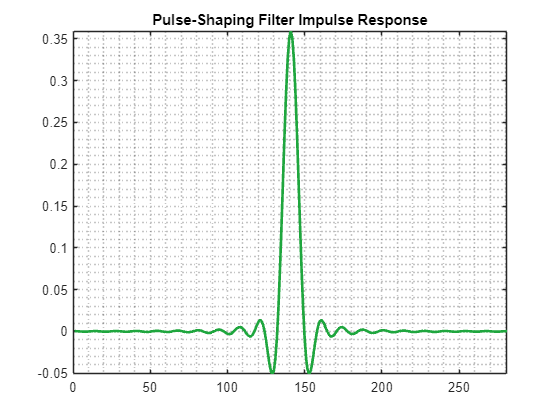

% Transmisor

beta=0.5;
lobs=28; %num lobulos
muestras=Upf; %num muestras entre lobulos
p=rcosdesign(beta,lobs,muestras);
figure
plot(p,'Color','#1fa63e','LineWidth',2),grid minor
title('Pulse-Shaping Filter Impulse Response')
xlim([0 length(p)])
ylim([min(p) max(p)])

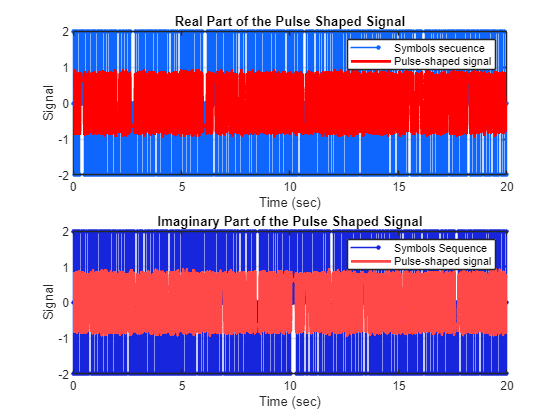


% Pulse Shaping

skf=conv(sk,p,"same");

t(length(t):length(sk))=max(t);

figure
subplot(211),stem(t,[real(sk) zeros(1,length(real(sk) )-length(real(sk) ))],'Color','#0f66fe','Marker','.','MarkerSize',10),grid on, hold on
plot(t,real(skf),'Color','r','LineWidth',2), hold on
title('Real Part of the Pulse Shaped Signal')
xlabel('Time (sec)') 
ylabel('Signal') 
legend('Symbols secuence','Pulse-shaped signal')
subplot(212),stem(t,[imag(sk)  zeros(1,length(imag(sk))-length(imag(sk)))],'Color','#1726dd','Marker','.','MarkerSize',10),grid on, hold on
plot(t,imag(skf),'Color','#ff4848','LineWidth',2), hold off
title('Imaginary Part of the Pulse Shaped Signal')
xlabel('Time (sec)') 
ylabel('Signal') 
legend('Symbols Sequence','Pulse-shaped signal')

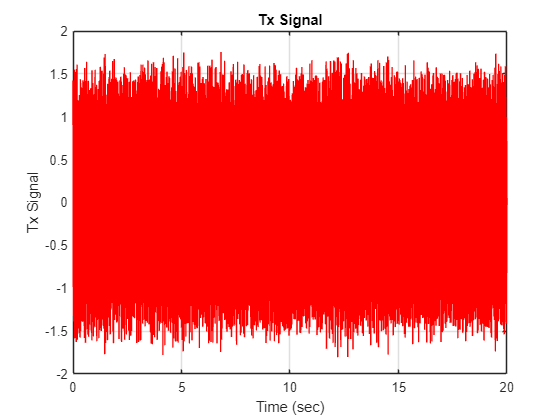


fc=50;
x=real(sqrt(2)*exp(1i*2*pi*fc*t).*skf);


figure
plot(t,x,'Color','r'), grid on
title('Tx Signal')
xlabel('Time (sec)') 
ylabel('Tx Signal') 

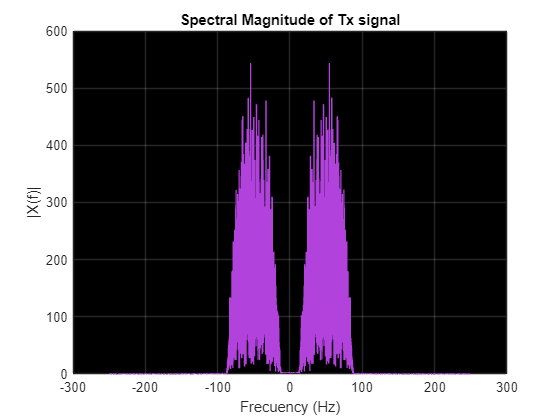

% Espectro de la señal transmitida

% X=fftshift(abs(fft(x)));
X=fftshift(fft(x));
f=linspace((-0.5*fs),(0.5*fs),length(X));

plot(f,abs(X),'Color','#b242dc'), grid, hold off
title('Spectral Magnitude of Tx signal')
xlabel('Frecuency (Hz)') 
ylabel('|X(f)|') 
set(gca,'Color','k')
set(gca,'GridColor','w')

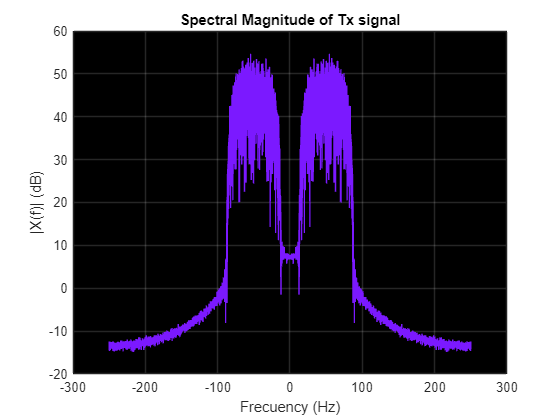


plot(f,db(abs(X)),'Color','#7b19ff'), grid, hold off
title('Spectral Magnitude of Tx signal')
xlabel('Frecuency (Hz)') 
ylabel('|X(f)| (dB)') 
set(gca,'Color','k')
set(gca,'GridColor','w')

% Canal
sigma=0.0;
z=sigma*randn(1,length(x));

y=x+z;

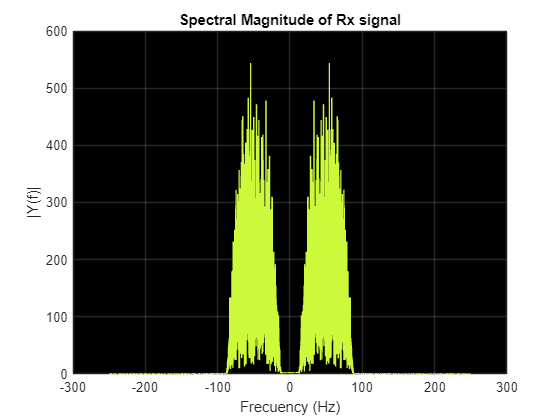

Y=fftshift(fft(y));
f=linspace((-0.5*fs),(0.5*fs),length(Y));

plot(f,abs(Y),'Color','#cdf93b'), grid, hold off
title('Spectral Magnitude of Rx signal')
xlabel('Frecuency (Hz)') 
ylabel('|Y(f)|') 
set(gca,'Color','k')
set(gca,'GridColor','w')

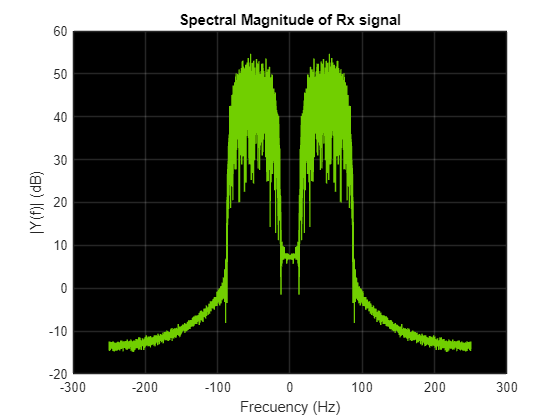


plot(f,db(abs(Y)),'Color','#71cf00'), grid, hold off
title('Spectral Magnitude of Rx signal')
xlabel('Frecuency (Hz)') 
ylabel('|Y(f)| (dB)') 
set(gca,'Color','k')
set(gca,'GridColor','w')

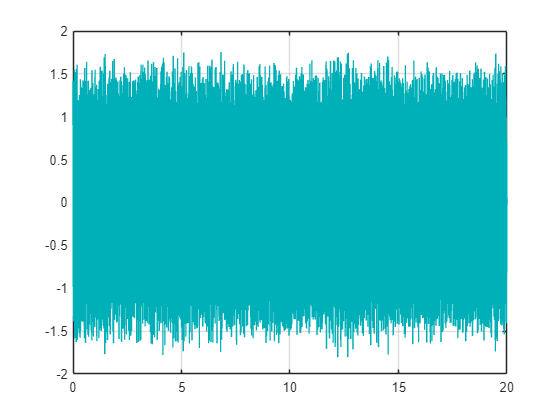

% Receptor
figure
plot(t,y,'Color','#00b0b9'),grid

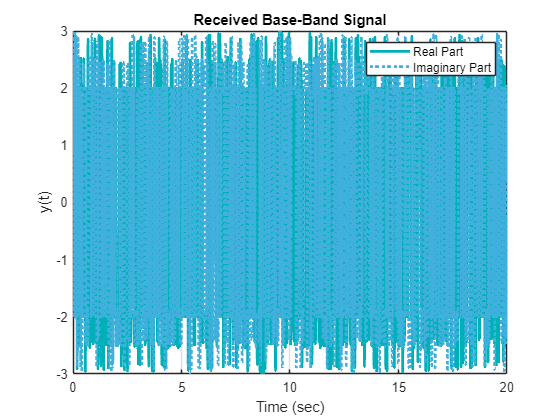


ybb=y.*(sqrt(2)*exp(-1i*2*pi*fc*t));
u=conv(ybb,flip(p),'same');

figure

plot(t,real(u),'Color','#00b0b9','LineWidth',2),grid on,hold on
plot(t,imag(u),'Color','#42b0dc','LineWidth',2,'LineStyle',':'),grid on,hold off
title('Received Base-Band Signal')
xlabel('Time (sec)') 
ylabel('y(t)') 
legend('Real Part','Imaginary Part')


u(1)=[]

u =    1.7538 - 1.3156i   1.9358 - 1.2805i   2.0765 - 1.1535i   2.1732 - 0.9357i   2.2271 - 0.6350i   2.2427 - 0.2656i   2.2276 + 0.1537i   2.1904 + 0.6012i   2.1400 + 1.0545i   2.0844 + 1.4920i   2.0296 + 1.8951i   1.9805 + 2.2485i   1.9401 + 2.5401i   1.9097 + 2.7606i   1.8892 + 2.9034i   1.8784 + 2.9645i   1.8780 + 2.9413i   1.8893 + 2.8316i   1.9137 + 2.6353i   1.9531 + 2.3547i   2.0093 + 1.9952i   2.0831 + 1.5656i   2.1717 + 1.0791i   2.2688 + 0.5546i   2.3645 + 0.0157i   2.4447 - 0.5104i   2.4922 - 0.9945i   2.4877 - 1.4076i   2.4129 - 1.7231i   2.2523 - 1.9205i   1.9957 - 1.9865i   1.6406 - 1.9163i   1.1949 - 1.7143i   0.6771 - 1.3942i   0.1155 - 0.9775i  -0.4536 - 0.4914i  -0.9890 + 0.0350i  -1.4476 + 0.5724i  -1.7891 + 1.0940i  -1.9810 + 1.5764i  -2.0028 + 2.0016i  -1.8489 + 2.3574i  -1.5293 + 2.6368i  -1.0699 + 2.8365i  -0.5108 + 2.9551i   0.0967 + 2.9929i   0.6962 + 2.9506i   1.2314 + 2.8288i   1.6518 + 2.6278i   1.9170 + 2.3485i


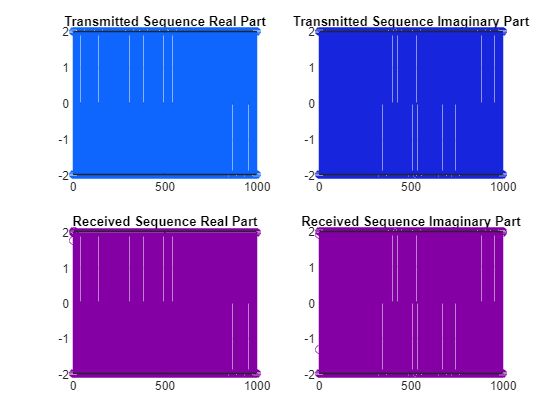

uk=downsample(u,Upf);
figure
subplot(221),stem(real(s),'Color','#0f66fe'),grid
title('Transmitted Sequence Real Part')
subplot(223),stem(real(uk),'Color','#8400a5'),grid
title('Received Sequence Real Part')
subplot(222),stem(imag(s),'Color','#1726dd'),grid
title('Transmitted Sequence Imaginary Part')
subplot(224),stem(imag(uk),'Color','#8400a5'),grid
title('Received Sequence Imaginary Part')

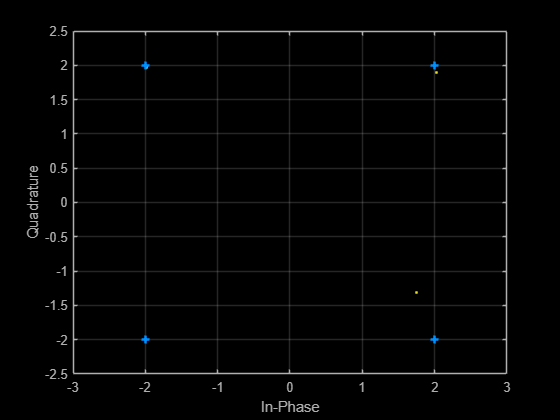


figure
scatter(real(uk), imag(uk),'MarkerEdgeColor','#e7e01f','Marker','.'),grid on,hold on
scatter(real(constell), imag(constell),'MarkerEdgeColor','#008fff','Marker','+','LineWidth',2),grid on
box on
ax = gca;
set(gcf,'Color','k')
set(ax,'Color','k')
set(ax,'GridColor','w')
set(ax,'XColor','#b0b0b0')
set(ax,'YColor','#b0b0b0')
xlabel('In-Phase') 
ylabel('Quadrature') 

% Decisor

eS=zeros(1,length(s));%Simbolos estimados

op=zeros(length(uk),length(constell));
aux1=constell(ones(1,length(uk)),:);
aux2=uk(ones(1,length(constell)),:).';
op=aux1-aux2;
[m, I]=min(abs(op),[],2);
eS=constell(I);

[numErr,SER]=symerr(s,eS)

numErr = 0

SER = 0